We set up advection over $[0,1]$ with velocity $c=-1$. This puts the right-side boundary in the upwind direction.

c = -1;  n = 100;
[x,Dx] = diffmat2(n,[0,1]);
uinit = exp(-100*(x-0.5).^2);

First we try imposing $u=0$ at the right boundary, by appending that value to the end of the vector before multiplying by the differentiation matrix.

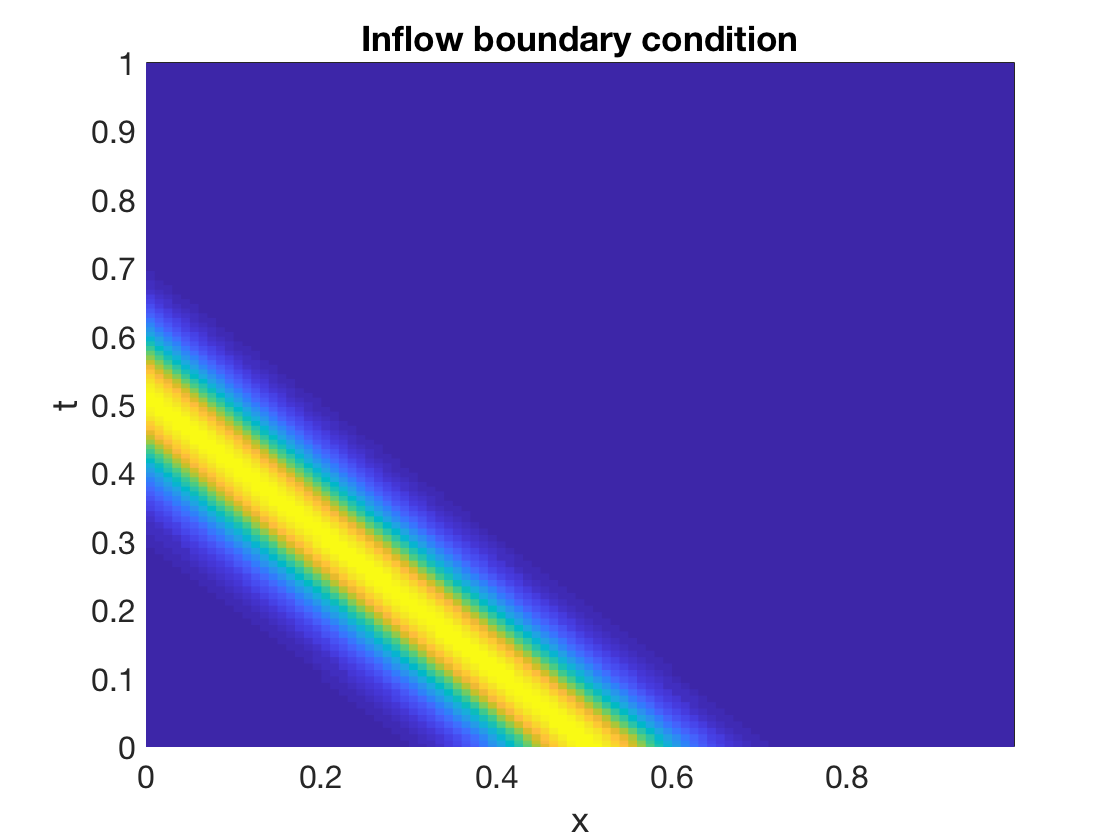

chop = @(u) u(1:n);  extend = @(v) [v;0];
odefun = @(t,v) -c*chop(Dx*extend(v));
[t,V] = ode113(odefun,[0,1],uinit(1:n));
pcolor(x(1:n),t,V)
xlabel x, ylabel t, shading flat    % ignore this line
title('Inflow boundary condition')   % ignore this line

The data from the initial condition propagates out of the left edge. Because only zero is coming in from the upwind direction, the solution remains zero thereafter.

Now we try $u=0$ imposed at the left boundary. 

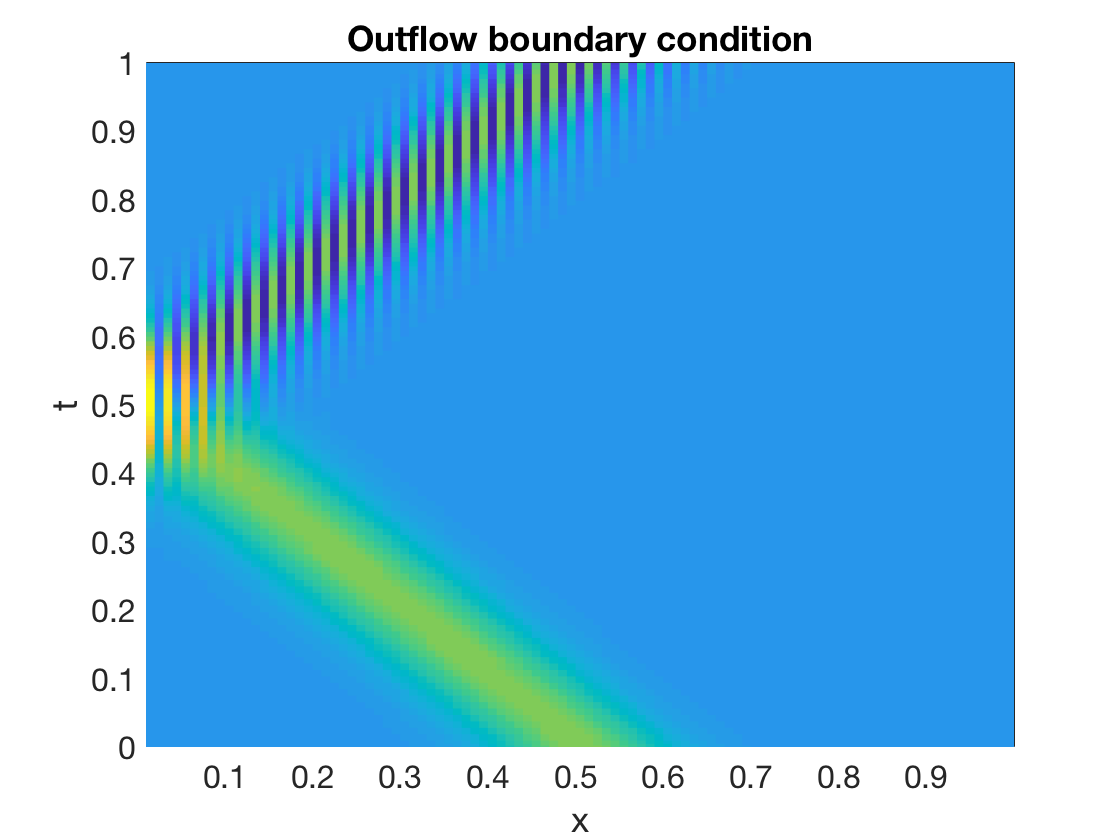

chop = @(u) u(2:n+1);  extend = @(v) [0;v];
odefun = @(t,v) -c*chop(Dx*extend(v));
[t,V] = ode113(odefun,[0,1],uinit(2:n+1));
pcolor(x(2:n+1),t,V)
xlabel x, ylabel t, shading flat     % ignore this line
title('Outflow boundary condition')   % ignore this line

Everything seems OK until the data begins to interact with the inappropriate boundary condition. The resulting ``reflection'' is entirely wrong for advection from right to left. 